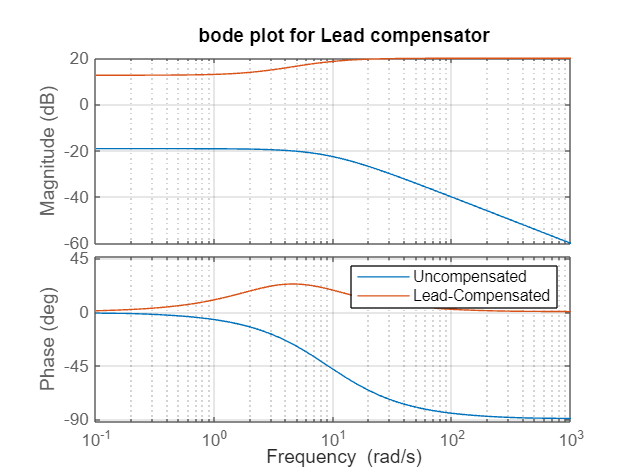

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

s = tf('s');
G = 1/(s + 9);
G_lead = 10*(s + 2)/(s + 7);
G_lag = (s + 3)/(s + 0.3);
G_total= G*G_lead*G_lag;
G_C=feedback(G_total,1); 
%%C_lead bode plots
figure;
bode(G, G_lead);
grid on;
title('bode plot for Lead compensator')
legend('Uncompensated', 'Lead-Compensated')

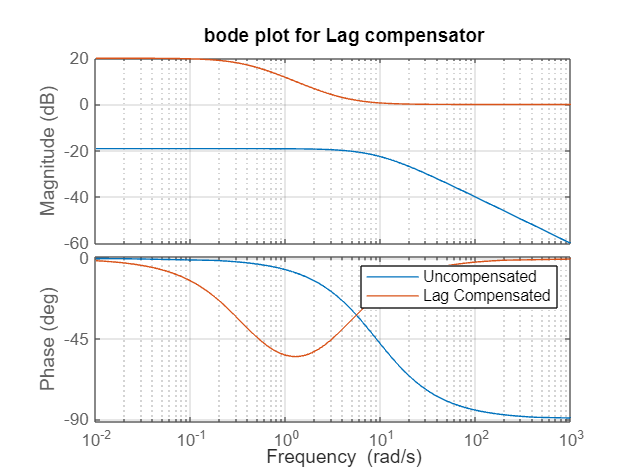

%%C-lag bode plot
figure;
bode(G, G_lag);
grid on;
title('bode plot for Lag compensator')
legend('Uncompensated', 'Lag Compensated')

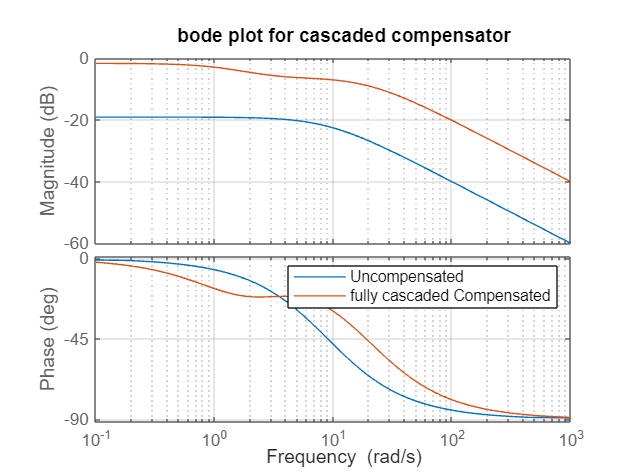

%%bode plot for cascaded ssytem vs Uncompensated
figure;
bode(G,G_C);
grid on;
title('bode plot for cascaded compensator')
legend('Uncompensated', 'fully Compensated')

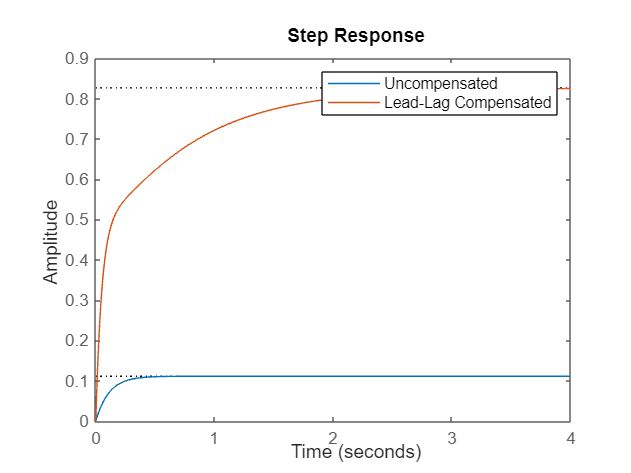

%%plotting the step response
step(G, G_C);
legend('Uncompensated', 'Lead-Lag Compensated')